## FUNWORK 5

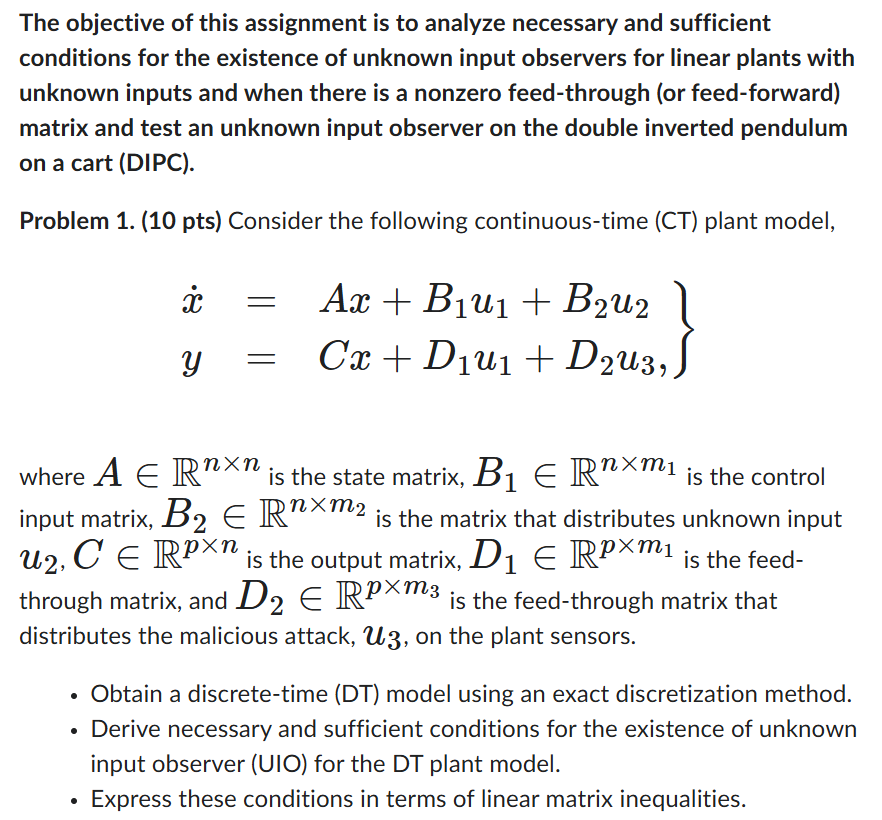


$$\begin{array}{l}
x_{\mathrm{dot}\;} =\mathrm{Ax}+B_1 u_1 +B_2 u_2 \\
y=\mathrm{Cx}+D_1 u_1 +D_2 u_3 \;\\
\mathrm{Discretizing}\;\mathrm{the}\;\mathrm{model}:\\
x\left\lbrack k+1\right\rbrack =e^{\mathrm{Ah}} x\left\lbrack k\right\rbrack +\int_0^h e^{A\eta } B_1 d\eta \;u_1 \left\lbrack k\right\rbrack \;+\int_0^h e^{A\eta } B_2 d\eta \;u_2 \left\lbrack k\right\rbrack \\
\;y\left\lbrack k\right\rbrack =\mathrm{Cx}\left\lbrack k\right\rbrack +D_1 u_1 \left\lbrack k\right\rbrack +D_2 u_3 \left\lbrack k\right\rbrack \\
\mathrm{Let}\;\;A_d =e^{\mathrm{Ah}} \;\;\Gamma_{1d} =\int_0^h e^{A\eta } B_1 d\eta \;\;\mathrm{and}\;\Gamma_{2d} =\int_0^h e^{A\eta } B_2 d\eta \;\\

\end{array}$$


Necessary and Sufficient Conditions for the existence of UIO:


$$\begin{array}{l}
x\left\lbrack k\right\rbrack =x\left\lbrack k\right\rbrack -\textrm{MCx}\left\lbrack k\right\rbrack +\textrm{MCx}\left\lbrack k\right\rbrack \\
\;\;\;\;\;\;\;\;=\left(I_n -\textrm{MC}\right)x\left\lbrack k\right\rbrack +M\left(y\left\lbrack k\right\rbrack -D_1 u_1 \left\lbrack k\right\rbrack -D_2 u_3 \left\lbrack k\right\rbrack \right)\\
\;\;\;\;\;\;\;\;=\left(I_n -\textrm{MC}\right)x\left\lbrack k\right\rbrack +\textrm{My}\left\lbrack k\right\rbrack -{\textrm{MD}}_1 u_1 \left\lbrack k\right\rbrack -{\textrm{MD}}_2 u_3 \left\lbrack k\right\rbrack 
\end{array}$$
    

**For the first necessary condition we have:**

${\textrm{MD}}_2 =0$  **  As we need the output of malicious attack to go to 0**


$$x\left\lbrack k\right\rbrack =\left(I_n -\mathrm{MC}\right)x\left\lbrack k\right\rbrack +\mathrm{My}\left\lbrack k\right\rbrack -{\mathrm{MD}}_1 u_1 \left\lbrack k\right\rbrack$$



$$\begin{array}{l}
z\left\lbrack k\right\rbrack =\left(I_n -\mathrm{MC}\right)x\left\lbrack k\right\rbrack \\
x\left\lbrack k\right\rbrack =z\left\lbrack k\right\rbrack +M\left(y\left\lbrack k\right\rbrack -D_1 u_1 \left\lbrack k\right\rbrack \right)\\
x_{\mathrm{est}} \left\lbrack k\right\rbrack =z\left\lbrack k\right\rbrack +M\left(y\left\lbrack k\right\rbrack -D_1 u_1 \left\lbrack k\right\rbrack \right)\\
z\left\lbrack k+1\right\rbrack =\left(I_n -\mathrm{MC}\right)x\left\lbrack k+1\right\rbrack \\
x\left\lbrack k+1\right\rbrack =\phi x\left\lbrack k\right\rbrack +\Gamma_{1d} u_1 \left\lbrack k\right\rbrack +\Gamma_{2d} u_2 \left\lbrack k\right\rbrack \\
z\left\lbrack k+1\right\rbrack =\left(I_n -\mathrm{MC}\right)\left(\phi x\left\lbrack k\right\rbrack +\Gamma_{1d} u_1 \left\lbrack k\right\rbrack +\Gamma_{2d} u_2 \left\lbrack k\right\rbrack \right)\\
z\left\lbrack k+1\right\rbrack =\left(I_n -\mathrm{MC}\right)\left(\phi \left(z\left\lbrack k\right\rbrack +M\left(y\left\lbrack k\right\rbrack -D_1 u_1 \left\lbrack k\right\rbrack \right)\right)+\Gamma_{1d} u_1 \left\lbrack k\right\rbrack +\Gamma_{2d} u_2 \left\lbrack k\right\rbrack \right)\\
z\left\lbrack k+1\right\rbrack =\left(I_n -\mathrm{MC}\right)\left(\left(\phi z+\phi \mathrm{My}\left\lbrack k\right\rbrack -{\phi \mathrm{MD}}_1 u_1 \left\lbrack k\right\rbrack \right)+\Gamma_{1d} u_1 \left\lbrack k\right\rbrack \right)+\left(I_n -\mathrm{MC}\right)\Gamma_{2d} u_2 \left\lbrack k\right\rbrack 
\end{array}$$


**This gives us our second necessary condition:**


$$\left(I-\mathrm{MC}\right)\Gamma_{2d} =0$$


**We can see that**


$$\begin{array}{l}
\left(I_n -\mathrm{MC}\right)\Gamma_{2d} =O\\
{\mathrm{MD}}_2 =O\\
\mathrm{rank}\left\lbrack \begin{array}{cc}
C\Gamma_{2d}  & D_2 \\
\Gamma_{2d}  & O
\end{array}\right\rbrack =\mathrm{rank}\;\left\lbrack C\Gamma_{2d\;} \;D_2 \right\rbrack 
\end{array}$$



$$\mathrm{rank}\left\lbrack C\Gamma_{2d} \;{\;D}_2 \;\right\rbrack =\mathrm{rank}\left(\Gamma_{2d} \right)+\mathrm{rank}\left(D_2 \right)$$


From the above two conditions.

**For the last condition we need the error dynamics matrix to by schur stable:**


$$\begin{array}{l}
e\left\lbrack k+1\right\rbrack =\left(I_n -\mathrm{MC}\right)\phi e\left\lbrack k\right\rbrack \\
A_1 =\left(I_n -\mathrm{MC}\right)\phi \\
e\left\lbrack k+1\right\rbrack =A_1 e\left\lbrack k\right\rbrack \\
y_{\mathrm{est}} \left\lbrack k\right\rbrack ={\mathrm{Cx}}_{\mathrm{est}} \left\lbrack k\right\rbrack =C\left(z\left\lbrack k\right\rbrack +M\left(y\left\lbrack k\right\rbrack -D_1 u_1 \left\lbrack k\right\rbrack \right)\right)\\
L\left(y\left\lbrack k\right\rbrack -y_{\mathrm{est}} \left\lbrack k\right\rbrack \right)\\
\mathrm{Adding}\;\mathrm{Luenberger}\;\mathrm{Innovation}\;\mathrm{term}:\\
e\left\lbrack k+1\right\rbrack =\left(A_1 -\mathrm{LC}\right)e\left\lbrack k\right\rbrack -{\mathrm{LD}}_2 u_2 \left\lbrack k\right\rbrack 
\end{array}$$


**For the stability, pair, **$\left(A_1 ,C\right)$** is detectable**

These were the three conditions.

**Representing them in terms of LMIs:**


$$\begin{array}{l}
e\left\lbrack k+1\right\rbrack =\mathrm{Ee}\left\lbrack k\right\rbrack +{\mathrm{Nu}}_2 \left\lbrack k\right\rbrack \;\mathrm{where}\;E=\left(A_1 -\mathrm{LC}\right)\;\mathrm{and}\;N=-{\mathrm{LD}}_2 \\
{\left(A_1 -\mathrm{LC}\right)}^T P\left(A_1 -\mathrm{LC}\right)-P\le 0\;\\
Z=\mathrm{PL}\\
\left\lbrack \begin{array}{cc}
E^T \mathrm{PE}-\left(1-\alpha \right)P & *\\
N^T \mathrm{PE} & N^T \mathrm{PN}-\alpha I
\end{array}\right\rbrack \le 0\\
\;\mathrm{The}\;\mathrm{LMI}:\\
\left\lbrack \begin{array}{cc}
-P & *\\
\Omega_{21}  & \Omega_{22} 
\end{array}\right\rbrack \le 0\\
\Omega_{21}^T =\;\left\lbrack {\mathrm{PA}}_1 -\mathrm{ZC}\;\;-\mathrm{ZC}\right\rbrack \\
\Omega_{22} =\left\lbrack \begin{array}{cc}
-\left(1-\alpha \right)P & O_{n\times m_2 } \\
O_{\mathrm{m2}\times n}  & -\alpha I
\end{array}\right\rbrack \\
\Omega_{22} +\Omega_{21} P\Omega_{21}^T \le 0\\

\end{array}$$
    

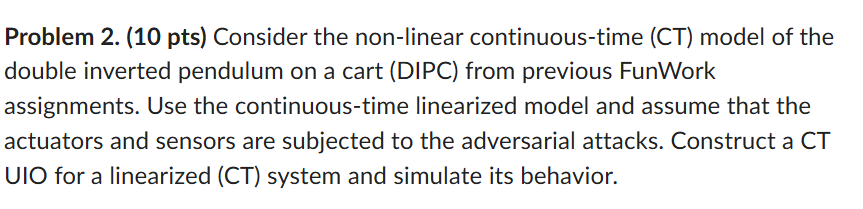

syms x1 x2 x3 x4 x5 x6 u
M = 1.5;
m1 = 0.5;
l1 = 0.5;
m2 = 0.75;
l2 = 0.75;
g = 9.81;
T_cart = 0.5*M*x4^2;
T_pendulum1 = 0.5*m1*((x4+l1*x5*cos(x2))^2 + (l1*x5*sin(x2))^2); 
T_pendulum2 = 0.5*m2*((x4 + l1*x5*cos(x2) + l2*x6*cos(x3))^2 + (l1*x5*sin(x2) + l2*x6*sin(x3))^2); 
T_total = simplify(T_cart + T_pendulum1 + T_pendulum2); 
V_Cart = 0;  
V_pendulum1 = m1*g*l1*cos(x2);
V_pendulum2 = m2*g*(l1*cos(x2)+l2*cos(x3));
V_total = simplify(V_Cart + V_pendulum1 + V_pendulum2); 
L = simplify(T_total - V_total);

dL_dx1 = diff(L, x1);
dL_dx2 = diff(L, x2);
dL_dx3 = diff(L, x3);
dL_dx4 = diff(L, x4);
dL_dx5 = diff(L, x5);
dL_dx6 = diff(L, x6);
q = [x1 ;x2; x3];
qd = [x4; x5; x6]; 
syms qdd1 qdd2 qdd3 real
qdd = [qdd1; qdd2; qdd3];
Jaco = jacobian([dL_dx4;dL_dx5;dL_dx6],[q;qd]);
d_dt_dLdqdot = Jaco*[qd; qdd];
dLdq = [dL_dx1;dL_dx2;dL_dx3];
Force = [u; 0; 0];
Lagrange_eq = simplify(d_dt_dLdqdot - dLdq -Force);
D = sym(zeros(3,3));
for i=1:3
  for j=1:3
    D(i,j) = simplify(diff(diff(T_total, qd(i)), qd(j)));
  end

end
D

$$D = \left(\begin{array}{ccc} \frac{11}{4} & \frac{5\,\cos\left(x_{2}\right)}{8} & \frac{9\,\cos\left(x_{3}\right)}{16}\\ \frac{5\,\cos\left(x_{2}\right)}{8} & \frac{5}{16} & \frac{9\,\cos\left(x_{2}-x_{3}\right)}{32}\\ \frac{9\,\cos\left(x_{3}\right)}{16} & \frac{9\,\cos\left(x_{2}-x_{3}\right)}{32} & \frac{27}{64} \end{array}\right)$$


G = simplify([ diff(V_total, x1);
      diff(V_total, x2);
      diff(V_total, x3) ])

$$G = \left(\begin{array}{c} 0\\ -\frac{981\,\sin\left(x_{2}\right)}{160}\\ -\frac{8829\,\sin\left(x_{3}\right)}{1600} \end{array}\right)$$


n = 3;
c = sym(zeros(n,n,n));
for i=1:n
  for j=1:n
    for k=1:n
      c(i,j,k) = 1/2*( diff(D(i,j), q(k)) + diff(D(i,k), q(j)) - diff(D(j,k), q(i)) );
    end
  end
end

C = sym(zeros(n,n));
for i=1:n
  for j=1:n
    C(i,j) = simplify( reshape(c(i,j,:),[n,1]).' * qd );
  end
end

H = [1;0;0];
qdd = simplify(D\(H*u - C*qd-G));
X = [q;qd];
f_sym = [qd; qdd]

$$f\_sym = \begin{array}{l} \left(\begin{array}{c} x_{4}\\ x_{5}\\ x_{6}\\ -\frac{280\,u-981\,\sin\left(2\,x_{2}\right)+100\,{x_{5}}^{2}\,\sin\left(x_{2}\right)+45\,{x_{6}}^{2}\,\sin\left(x_{3}\right)-120\,u\,\cos\left(\sigma_{3}\right)+45\,{x_{6}}^{2}\,\sigma_{1}}{20\,\sigma_{2}}\\ \frac{1575\,{x_{6}}^{2}\,\sin\left(x_{2}-x_{3}\right)-30411\,\sin\left(x_{2}\right)-8829\,\sin\left(x_{2}-2\,x_{3}\right)+250\,{x_{5}}^{2}\,\sin\left(2\,x_{2}\right)+1400\,u\,\cos\left(x_{2}\right)+450\,{x_{5}}^{2}\,\sin\left(\sigma_{3}\right)-600\,u\,\cos\left(x_{2}-2\,x_{3}\right)+225\,{x_{6}}^{2}\,\sin\left(x_{2}+x_{3}\right)}{50\,\sigma_{2}}\\ -\frac{300\,\sin\left(x_{2}-x_{3}\right)\,{x_{5}}^{2}+135\,\sin\left(\sigma_{3}\right)\,{x_{6}}^{2}-2943\,\sigma_{1}+2943\,\sin\left(x_{3}\right)+200\,u\,\cos\left(2\,x_{2}-x_{3}\right)-200\,u\,\cos\left(x_{3}\right)}{75\,\cos\left(2\,x_{2}\right)+135\,\cos\left(\sigma_{3}\right)-390} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\sin\left(2\,x_{2}-x_{3}\right)\\ \sigma_{2}=5\,\cos\left(2\,x_{2}\right)+9\,\cos\left(\sigma_{3}\right)-26\\ \sigma_{3}=2\,x_{2}-2\,x_{3} \end{array}$$

D_inv = inv(D)

$$D\_inv = \begin{array}{l} \left(\begin{array}{ccc} \frac{4\,\left(3\,{\cos\left(x_{2}-x_{3}\right)}^{2}-5\right)}{\sigma_{4}} & \sigma_{2} & \sigma_{3}\\ \sigma_{2} & \frac{16\,\left(3\,{\cos\left(x_{3}\right)}^{2}-11\right)}{\sigma_{4}} & \sigma_{1}\\ \sigma_{3} & \sigma_{1} & \frac{320\,\left(5\,{\cos\left(x_{2}\right)}^{2}-11\right)}{27\,\sigma_{4}} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{32\,\left(11\,\cos\left(x_{2}-x_{3}\right)-5\,\cos\left(x_{2}\right)\,\cos\left(x_{3}\right)\right)}{3\,\sigma_{4}}\\ \sigma_{2}=\frac{8\,\left(5\,\cos\left(x_{2}\right)-3\,\cos\left(x_{2}-x_{3}\right)\,\cos\left(x_{3}\right)\right)}{\sigma_{4}}\\ \sigma_{3}=\frac{80\,\left(\cos\left(x_{3}\right)-\cos\left(x_{2}-x_{3}\right)\,\cos\left(x_{2}\right)\right)}{3\,\sigma_{4}}\\ \sigma_{4}=33\,{\cos\left(x_{2}-x_{3}\right)}^{2}-30\,\cos\left(x_{2}-x_{3}\right)\,\cos\left(x_{2}\right)\,\cos\left(x_{3}\right)+25\,{\cos\left(x_{2}\right)}^{2}+15\,{\cos\left(x_{3}\right)}^{2}-55 \end{array}$$

C

$$C = \left(\begin{array}{ccc} 0 & -\frac{5\,x_{5}\,\sin\left(x_{2}\right)}{8} & -\frac{9\,x_{6}\,\sin\left(x_{3}\right)}{16}\\ 0 & 0 & \frac{9\,x_{6}\,\sin\left(x_{2}-x_{3}\right)}{32}\\ 0 & -\frac{9\,x_{5}\,\sin\left(x_{2}-x_{3}\right)}{32} & 0 \end{array}\right)$$

syms u_1 u_2
 u_new = [u_1; u_2];
 H_new = [1 0;
        0 1;
        0 0];
 qdd_new_1 = simplify(D\(H_new*u_new - C*qd-G));
 X_new_1 = [q;qd];
 f_sym_new_1 = [qd; qdd_new_1]

$$f\_sym\_new\_1 = \begin{array}{l} \left(\begin{array}{c} x_{4}\\ x_{5}\\ x_{6}\\ -\frac{280\,u_{1}-981\,\sin\left(2\,x_{2}\right)+100\,{x_{5}}^{2}\,\sin\left(x_{2}\right)+45\,{x_{6}}^{2}\,\sin\left(x_{3}\right)-120\,u_{1}\,\cos\left(\sigma_{4}\right)-560\,u_{2}\,\cos\left(x_{2}\right)+45\,{x_{6}}^{2}\,\sigma_{1}+240\,u_{2}\,\sigma_{2}}{20\,\sigma_{3}}\\ \frac{1200\,u_{2}\,\cos\left(2\,x_{3}\right)-8829\,\sin\left(x_{2}-2\,x_{3}\right)-30411\,\sin\left(x_{2}\right)-7600\,u_{2}+1575\,{x_{6}}^{2}\,\sin\left(x_{2}-x_{3}\right)+250\,{x_{5}}^{2}\,\sin\left(2\,x_{2}\right)+1400\,u_{1}\,\cos\left(x_{2}\right)+450\,{x_{5}}^{2}\,\sin\left(\sigma_{4}\right)-600\,u_{1}\,\sigma_{2}+225\,{x_{6}}^{2}\,\sin\left(x_{2}+x_{3}\right)}{50\,\sigma_{3}}\\ -\frac{300\,\sin\left(x_{2}-x_{3}\right)\,{x_{5}}^{2}+135\,\sin\left(\sigma_{4}\right)\,{x_{6}}^{2}-2943\,\sigma_{1}+2943\,\sin\left(x_{3}\right)+200\,u_{1}\,\cos\left(2\,x_{2}-x_{3}\right)+400\,u_{2}\,\cos\left(x_{2}+x_{3}\right)-200\,u_{1}\,\cos\left(x_{3}\right)-1360\,u_{2}\,\cos\left(x_{2}-x_{3}\right)}{75\,\cos\left(2\,x_{2}\right)+135\,\cos\left(\sigma_{4}\right)-390} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\sin\left(2\,x_{2}-x_{3}\right)\\ \sigma_{2}=\cos\left(x_{2}-2\,x_{3}\right)\\ \sigma_{3}=5\,\cos\left(2\,x_{2}\right)+9\,\cos\left(\sigma_{4}\right)-26\\ \sigma_{4}=2\,x_{2}-2\,x_{3} \end{array}$$

syms u_e1 u_e2 real
q_val_1 = [0.1; deg2rad(60); deg2rad(45)];
qd_val_1 = [0; 0; 0];
G_val = double(subs(G, [x1 x2 x3 x4 x5 x6], [q_val_1' qd_val_1']));
eq = H_new*[u_e1 ; u_e2] == G_val;
sol_u = solve(eq, u_e1, u_e2, 'Real', true)

sol_u = struct with fields:
    u_e1: [0×1 sym]
    u_e2: [0×1 sym]


syms u_3 u_e3 real
u_new_2 = [u_1; u_2; u_3];
H_new_2 = [1 0 0;
        0 1 0 ;
        0 0 1];
qdd_new_2 = simplify(D\(H_new_2*u_new_2 - C*qd-G));
X_new_2 = [q;qd];
f_sym_new_2 = [qd; qdd_new_2]

$$f\_sym\_new\_2 = \begin{array}{l} \left(\begin{array}{c} x_{4}\\ x_{5}\\ x_{6}\\ -\frac{840\,u_{1}-2943\,\sin\left(2\,x_{2}\right)+300\,{x_{5}}^{2}\,\sin\left(x_{2}\right)+135\,{x_{6}}^{2}\,\sin\left(x_{3}\right)-360\,u_{1}\,\cos\left(\sigma_{5}\right)+800\,u_{3}\,\sigma_{2}-1680\,u_{2}\,\cos\left(x_{2}\right)-800\,u_{3}\,\cos\left(x_{3}\right)+135\,{x_{6}}^{2}\,\sigma_{1}+720\,u_{2}\,\sigma_{3}}{60\,\sigma_{4}}\\ \frac{3600\,u_{2}\,\cos\left(2\,x_{3}\right)-26487\,\sin\left(x_{2}-2\,x_{3}\right)-91233\,\sin\left(x_{2}\right)-22800\,u_{2}+4725\,{x_{6}}^{2}\,\sin\left(x_{2}-x_{3}\right)+750\,{x_{5}}^{2}\,\sin\left(2\,x_{2}\right)-4000\,u_{3}\,\cos\left(x_{2}+x_{3}\right)+4200\,u_{1}\,\cos\left(x_{2}\right)+1350\,{x_{5}}^{2}\,\sin\left(\sigma_{5}\right)-1800\,u_{1}\,\sigma_{3}+13600\,u_{3}\,\cos\left(x_{2}-x_{3}\right)+675\,{x_{6}}^{2}\,\sin\left(x_{2}+x_{3}\right)}{150\,\sigma_{4}}\\ -\frac{2700\,\sin\left(x_{2}-x_{3}\right)\,{x_{5}}^{2}+1215\,\sin\left(\sigma_{5}\right)\,{x_{6}}^{2}+13600\,u_{3}-26487\,\sigma_{1}+26487\,\sin\left(x_{3}\right)-4000\,u_{3}\,\cos\left(2\,x_{2}\right)+1800\,u_{1}\,\sigma_{2}+3600\,u_{2}\,\cos\left(x_{2}+x_{3}\right)-1800\,u_{1}\,\cos\left(x_{3}\right)-12240\,u_{2}\,\cos\left(x_{2}-x_{3}\right)}{135\,\sigma_{4}} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\sin\left(2\,x_{2}-x_{3}\right)\\ \sigma_{2}=\cos\left(2\,x_{2}-x_{3}\right)\\ \sigma_{3}=\cos\left(x_{2}-2\,x_{3}\right)\\ \sigma_{4}=5\,\cos\left(2\,x_{2}\right)+9\,\cos\left(\sigma_{5}\right)-26\\ \sigma_{5}=2\,x_{2}-2\,x_{3} \end{array}$$

q_val_1 = [0.1; deg2rad(60); deg2rad(45)];
qd_val_1 = [0; 0; 0];
G_val = double(subs(G, [x1 x2 x3 x4 x5 x6], [q_val_1' qd_val_1']));
eq = H_new_2*[u_e1 ; u_e2 ; u_e3] == G_val;
sol_u = solve(eq, u_e1, u_e2, u_e3, 'Real', true);
u_e_new = double(struct2array(sol_u))

u_e_new =          0   -5.3098   -3.9019


A_sym_new = simplify(jacobian(f_sym_new_2, X));
B_sym_new = simplify(jacobian(f_sym_new_2, u_new_2));
vars = [x1; x2; x3; x4; x5; x6; u_1; u_2; u_3];
vals = [0.1; deg2rad(60); deg2rad(45); 0; 0; 0; u_e_new'];

A_lin_syms_new = double(subs(A_sym_new, vars, vals))

A_lin_syms_new =          0         0         0    1.0000         0         0
         0         0         0         0    1.0000         0
         0         0         0         0         0    1.0000
         0   -0.5341   -1.1264         0         0         0
         0   22.5046  -17.8041         0         0         0
         0  -13.9883   21.7759         0         0         0


B_lin_syms_new = double(subs(B_sym_new, vars, vals))

B_lin_syms_new =          0         0         0
         0         0         0
         0         0         0
    0.4252   -0.1742   -0.2887
   -0.1742    7.3409   -4.5629
   -0.2887   -4.5629    5.5808


C_new = [1 0 0 0 0 0;
    0 1 0 0 0 0;
    0 0 1 0 0 0;
    0 0 0 1 0 0];

I will now solve question 2, I will choose my matrices B1 and B2 as well, and I will assume that the attack on the first entry of B.

%Feasibility check for M, Before that Let us create B2 Matrix
%Let's do a feasibility check for possibility of choosing M
B2 = [1; 0; 0; 0; 0; 0];
rankB2 = rank(B2);
rankCB2 = rank(C_new*B2);

Now I will choose D2 as (3,1) as I will consider the attack on second entry of C, basically same as B. I am choosing attacks on the the position actuation and angular sensing.

D2 = [0; 0; 1; 0];
rankD2 = rank(D2);
if rank([C_new*B2, D2]) == rankB2+rankD2
    fprintf('FEASIBLE')
else 
    fprintf('Unfeasible')
end

FEASIBLE

Target = [C_new*B2 D2];
O = zeros(6, 1);
B2O = [B2 O];
M = B2O*pinv(Target)

M =      1     0     0     0
     0     0     0     0
     0     0     0     0
     0     0     0     0
     0     0     0     0
     0     0     0     0


Now we need the LMI conditions to satisfy, first thing to notice here is that A_1 = (I-MC)A which we will use for creating the luenberger observer


$$\begin{array}{l}
e\left\lbrack k+1\right\rbrack =\left(I-\textrm{MC}\right)\textrm{Ae}\left\lbrack k\right\rbrack \\
e\left\lbrack k+1\right\rbrack =A_1 e\left\lbrack k\right\rbrack 
\end{array}$$
    

Also in our equations we are using linearized matrices, that means we

n0 = size(A_lin_syms_new,1)

n0 = 6

A1 = (eye(n0) - M*C_new)*A_lin_syms_new

A1 =          0         0         0         0         0         0
         0         0         0         0    1.0000         0
         0         0         0         0         0    1.0000
         0   -0.5341   -1.1264         0         0         0
         0   22.5046  -17.8041         0         0         0
         0  -13.9883   21.7759         0         0         0


obsv_rank = rank(obsv(A1, C_new));
if obsv_rank < 6
    fprintf('System is Undetectable (Rank %d/6). CVX will fail.\n', obsv_rank);
else
    fprintf('System is Detectable. Proceeding to CVX.\n');
end

System is Detectable. Proceeding to CVX.


One of the main conditions fail, let us design a controller to resolve this issue

p = size(C_new,1);
cvx_begin sdp
    variable P(n0,n0) symmetric
    variable Y(n0,p)
    subject to
        P >= eye(n0) * 1e-6; % Ensure P is positive definite
        A1'*P + P*A1 - C_new'*Y' - Y*C_new <= -0.1*eye(n0);
        Y*D2 == 0;
cvx_end

 
Calling SDPT3 4.0: 53 variables, 14 equality constraints
------------------------------------------------------------

 num. of constraints = 14
 dim. of sdp    var  = 12,   num. of sdp  blk  =  2
 dim. of free   var  = 11 *** convert ublk to lblk
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
   HKM      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|3.3e+02|1.5e+02|1.5e+04| 0.000000e+00  0.000000e+00| 0:0:00| chol  1  1 
 1|0.953|0.855|1.6e+01|2.1e+01|7.8e+02| 0.000000e+00  1.461645e+00| 0:0:00| chol  1  1 
 2|0.843|0.747|2.4e+00|5.4e+00|1.4e+02| 0.000000e+00  1.096103e+00| 0:0:00| chol  1  1 
 3|1.000|0.870|4.5e-06|7.0e-01|1.8e+01| 0.000000e+00  6.147966e-01| 0:0:00|

if strcmp(cvx_status, 'Solved')
    Luen = P\Y
    fprintf('CVX Solved. Luenberger Gain Computed')
else
    error('ERRRRRRRRROOROR')
end

Luen =     0.5761    0.0000         0    0.0000
   -0.0000   12.0514         0   10.2523
    0.0000  -33.5421         0  -36.3061
   -0.0000    4.8730         0    7.0015
   -0.0000  168.0745         0  150.2734
    0.0000 -201.1905         0 -203.8602


CVX Solved. Luenberger Gain Computed

Let's see if L  is stable

eig(A1-Luen*C_new)

ans =   -0.5761 + 0.0000i
  -6.8654 + 8.0388i
  -6.8654 - 8.0388i
  -0.9094 + 1.2644i
  -0.9094 - 1.2644i
  -3.5033 + 0.0000i


Eigenvalues in open left hand plane, this confirms stability

N = -Luen*D2

N =      0
     0
     0
     0
     0
     0


E = A1-Luen*C_new;
if A1*B2 == 0
    fprintf('Pass')
else
    fprintf('Not Pass')
end

Pass

Q_lqr = diag([100, 100, 100, 1, 1, 1]); 
R_lqr = diag([1, 1, 1]);
K_fb = lqr(A_lin_syms_new, B_lin_syms_new, Q_lqr, R_lqr)

K_fb =     9.9941   -0.1934   -0.3089    7.4080    0.5278    0.6771
    0.1793   13.5213   -0.2088    0.7044    2.7766    1.1131
    0.2913    0.1979   14.6297    0.9677    1.2039    3.3596


eig(A_lin_syms_new-B_lin_syms_new*K_fb)

ans =   -1.3464 + 1.3037i
  -1.3464 - 1.3037i
  -3.7513 + 2.4267i
  -3.7513 - 2.4267i
 -10.4128 + 2.9834i
 -10.4128 - 2.9834i


Stable controller

%% 1. Setup & Equilibrium Definitions
dt = 0.001;                 
T_sim = 15;                  
time = 0:dt:T_sim;
steps = length(time);
F = E;                     
T = eye(6) - M*C_new;      
H = M;                     
K_obs = Luen + F*M;

% Define Equilibrium Points from your variables
x_eq = vals(1:6);           
u_eq = vals(7:9);
y_eq = C_new * x_eq;        % Output at equilibrium

% Initial Conditions
x_current = x_eq;           % Start exactly at equilibrium
z_current = zeros(6,1);     % Observer starts with 0 deviation

% Storage
X_hist = zeros(6, steps);
X_hat_hist = zeros(6, steps);

fprintf('Starting Linearized Simulation (Deviation Model)...\n');

Starting Linearized Simulation (Deviation Model)...


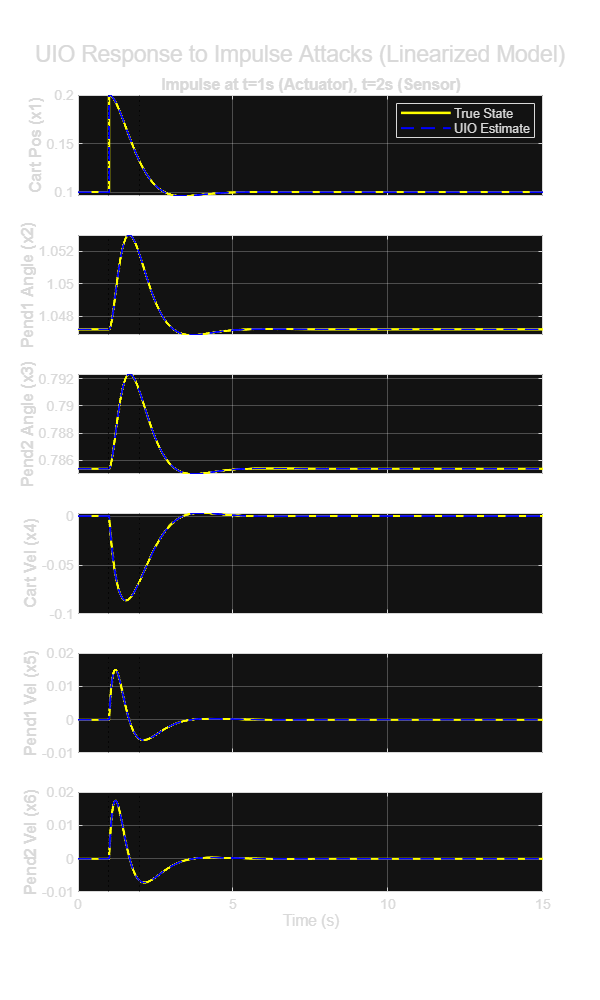


%% 2. Run Simulation Loop
for k = 1:steps
    t = time(k);
    
    % --- 1. Define IMPULSE Attacks ---
    % Actuator Impulse at t = 1.0s
    if abs(t - 1.0) < dt/2
        f_attack = 100; 
    else
        f_attack = 0;
    end
    
    % Sensor Impulse at t = 2.0s
    if abs(t - 2.0) < dt/2
        s_attack = 10; 
    else
        s_attack = 0;
    end
    
    % --- 2. Calculate Deviations ---
    % The linear matrices A and B operate on these deltas
    delta_x = x_current - x_eq;
    
    % --- 3. Measurements ---
    % Absolute measurement (what the sensor reads)
    y_abs = C_new * x_current + D2 * s_attack;
    
    % Deviation measurement (what the observer expects)
    delta_y = y_abs - y_eq;
    
    delta_x_hat = z_current + H * delta_y;
    
    % Reconstruct absolute estimate
    x_hat = delta_x_hat + x_eq;
    
    % --- 5. Control Law ---
    % Control minimizes error between Estimate and Equilibrium
    % u = u_eq - K * (x_hat - x_eq)
    u_ctrl = u_eq - K_fb * delta_x_hat;
    
    % Deviation Input
    delta_u = u_ctrl - u_eq;
    
    % --- 6. Dynamics Integration (Linearized Model) ---
    % dx = A*(x-xe) + B*(u-ue) + B2*attack
    dx = A_lin_syms_new * delta_x + ...
         B_lin_syms_new * delta_u + ...
         B2 * f_attack;
     
    % dz = F*z + T*B*delta_u + K*delta_y
    dz = F * z_current + ...
         T * B_lin_syms_new * delta_u + ...
         K_obs * delta_y;
     
    % Update States
    x_current = x_current + dx * dt;
    z_current = z_current + dz * dt;
    
    % Store absolute values for plotting
    X_hist(:, k) = x_current;
    X_hat_hist(:, k) = x_hat;
end

%% 3. Plot Results (One Graph Per Line)
% Make the figure tall and narrow to accommodate 6 stacked plots
figure('Color', 'w', 'Position', [100, 50, 600, 1000]); 
sgtitle('UIO Response to Impulse Attacks (Linearized Model)');

state_names = {'Cart Pos (x1)', 'Pend1 Angle (x2)', 'Pend2 Angle (x3)', ...
               'Cart Vel (x4)', 'Pend1 Vel (x5)', 'Pend2 Vel (x6)'};

for i = 1:6
    % Change subplot to (6 rows, 1 column, index i)
    subplot(6, 1, i);
    
    plot(time, X_hist(i,:), 'y', 'LineWidth', 1.5); hold on;
    plot(time, X_hat_hist(i,:), 'b--', 'LineWidth', 1.2);
    
    % Visual markers for attacks
    xline(1, 'k:', 'HandleVisibility', 'off'); 
    xline(2, 'k:', 'HandleVisibility', 'off');
    
    ylabel(state_names{i}, 'FontWeight', 'bold');
    grid on;
    
    % Only put the legend on the first plot to save space
    if i == 1
        legend('True State', 'UIO Estimate', 'Location', 'best');
        title('Impulse at t=1s (Actuator), t=2s (Sensor)');
    end
    
    if i == 6
        xlabel('Time (s)');
    else
        set(gca, 'XTickLabel', []); % Hide x-axis numbers for cleaner look
    end
end

shg;


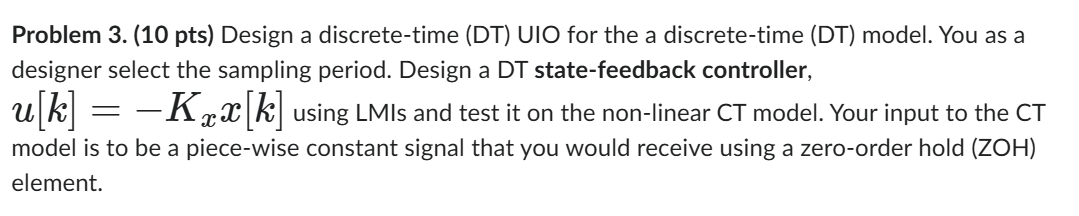

First Step; discretizing the model

Ts = 0.01;
sys = ss(A_lin_syms_new, B_lin_syms_new, C_new, 0);
sys_d = c2d(sys, Ts, 'zoh');
Ad = sys_d.A;
Bd = sys_d.B;
D2d = D2;

n = size(A_lin_syms_new, 1);
m2 = size(B2, 2);

Augmented_Matrix = [A_lin_syms_new,   B2;
                    zeros(m2, n),     zeros(m2, m2)];

Exp_Aug = expm(Augmented_Matrix * Ts);

% 3. Extract Discrete Matrices
A_d = Exp_Aug(1:n, 1:n);          
B2_d = Exp_Aug(1:n, n+1:end); 

fprintf('Exact Discrete B2_d computed via Augmented Matrix Exp.\n');

Exact Discrete B2_d computed via Augmented Matrix Exp.


disp(B2_d);

    0.0100
         0
         0
         0
         0
         0




Target_Discrete = [C_new*B2d, D2d];
B2O_disc = [B2_d, zeros(6,1)];
Md = B2O_disc*pinv(Target_Discrete)

Md =      1     0     0     0
     0     0     0     0
     0     0     0     0
     0     0     0     0
     0     0     0     0
     0     0     0     0


if rank([C_new*B2_d, D2d]) == rank(B2_d)+rank(D2d)
    fprintf('FEASIBLE')
else 
    fprintf('Unfeasible')
end

FEASIBLE

A1d = (eye(6) - Md*C_new) * Ad

A1d =          0         0         0         0         0         0
         0    1.0011   -0.0009         0    0.0100   -0.0000
         0   -0.0007    1.0011         0   -0.0000    0.0100
         0   -0.0053   -0.0113    1.0000   -0.0000   -0.0001
         0    0.2252   -0.1782         0    1.0011   -0.0009
         0   -0.1400    0.2179         0   -0.0007    1.0011


if Md*D2d == 0
    fprintf('PASS')
else
    fprintf('fail')
end

PASS

%Checking for feasibility
obsv_rank_disc = rank(obsv(A1d, C_new));
if obsv_rank_disc < 6
    fprintf('System is Undetectable (Rank %d/6). CVX will fail.\n', obsv_rank_disc);
else
    fprintf('System is Detectable. Proceeding to CVX.\n');
end

System is Detectable. Proceeding to CVX.


if A1d*B2d == 0
    fprintf('Pass')
else 
    fprintf('Failure')
end

Pass

Md*D2d

ans =      0
     0
     0
     0
     0
     0


% 1. Compute Controllability Matrix for the PLANT (Ad, Bd)
Co = ctrb(Ad, Bd);

% 2. Check Rank
rank_Co = rank(Co);

fprintf('Controllability Check:\n');

Controllability Check:


fprintf('Rank of ctrb(Ad, Bd) = %d / 6\n', rank_Co);

Rank of ctrb(Ad, Bd) = 6 / 6



if rank_Co == 6
    fprintf('>> SUCCESS: The system is Controllable. You can design K.\n');
else
    fprintf('>> FAILURE: The system is NOT Controllable.\n');
end

>> SUCCESS: The system is Controllable. You can design K.


alpha = 0.5; 

% Determine disturbance dimension r from D2d (should be 1 based on your D2)
r = size(D2d, 2); 
n = size(A1d, 1);

cvx_begin sdp quiet
    variable P(n,n) symmetric
    variable Z(n, size(C_new,1))
    
    % Omega21_T = [ PA1 - ZC,  -ZD ]  
    Phi = P*A1d - Z*C_new;
    Omega21_T = [Phi, -Z*D2d]; % Size: n x (n+r) (6x7)
    
    % Omega22 = diag(-(1-alpha)P, -alpha*I) 
    % FIXED: The identity matrix must match disturbance size 'r', not 'n'
    Omega22 = [ -(1-alpha)*P,      zeros(n, r);
                 zeros(r, n),      -alpha*eye(r) ];
             
    subject to
        P >= eye(n) * 1e-4; 
    
        
        [ -P,           Omega21_T;
          Omega21_T',   Omega22   ] <= 0;
        %Z*D2d == 0;
cvx_end

if strcmp(cvx_status, 'Solved')
    L_disc = P \ Z;
    fprintf('Discrete UIO Gain Found.\n');
else
    error('LMI Failed. Try reducing alpha or checking D2d dimensions.');
end

Discrete UIO Gain Found.


if strcmp(cvx_status, 'Solved')
    L_disc = P \ Z;
    fprintf('Discrete UIO Gain Found.\n');
    
    % Compute Final Matrices
    Fd = A1d - L_disc * C_new;
    Td = eye(6) - Md * C_new;
    Hd = Md;
    Kd_obs = L_disc + Fd * Md;
    
    disp('Eigenvalues of Discrete Error Dynamics (should be inside unit circle):');
    disp(abs(eig(Fd)));
else
    error('LMI Failed. Try reducing alpha.');
end

Discrete UIO Gain Found.


Eigenvalues of Discrete Error Dynamics (should be inside unit circle):


    0.0000
    0.5808
    0.5808
    0.1735
    0.0260
    0.0465




n = size(Ad,1);
m = size(Bd,2);

rho = 0.99;            
eps_small = 1e-8;

p_min = 1e-5;         % try 1e-2 ... 1e-5 (decrease if infeasible)
p_max = 1e6;          % try 1e3 ... 1e6 (increase if infeasible)

alpha = 1.0;          % weight on norm(Y)
beta  = 1e-3;         % weight on trace(P)

cvx_begin sdp quiet
    cvx_precision high
    variable P(n,n) symmetric
    variable Y(m,n)

    minimize( alpha * norm(Y,'fro') + beta * trace(P) )

    subject to
        P >= p_min * eye(n);
        P <= p_max * eye(n);

        LMI = [ -rho^2 * P,   (Ad*P - Bd*Y)';
                (Ad*P - Bd*Y),  -P ];
        LMI <= -eye(2*n)*eps_small;

cvx_end

if exist('P','var') && exist('Y','var') && (rank(P) == n)
    K_lmi = Y / P;            
    Acl = Ad - Bd*K_lmi;
    ev = eig(Acl);
    fprintf('Closed-loop eigenvalues (abs):\n'); disp(abs(ev)');
    fprintf('Max abs eigenvalue = %.6f\n', max(abs(ev)));
    fprintf('norm(K) (Fro) = %g, norm(K,inf) = %g\n', norm(K_lmi,'fro'), norm(K_lmi,inf));
    fprintf('cond(P) = %g, trace(P) = %g\n', cond(P), trace(P));
else
    error('P/Y not available or P singular.');
end

Closed-loop eigenvalues (abs):
    0.9423    0.9894    0.9894    0.9774    0.9867    0.9874



Max abs eigenvalue = 0.989421


norm(K) (Fro) = 11.7065, norm(K,inf) = 15.5746


cond(P) = 33.5848, trace(P) = 0.000672839


K_lmi

K_lmi =     6.9389    0.6462    0.7910    5.8333    0.5938    0.7714
    0.7368    4.1712    0.4732    0.5786    1.1956    0.7011
    0.9282    0.6278    5.2527    0.7297    0.7422    1.5886


eig(Ad-Bd*K_lmi)

ans =    0.9423 + 0.0000i
   0.9894 + 0.0117i
   0.9894 - 0.0117i
   0.9774 + 0.0000i
   0.9867 + 0.0000i
   0.9874 + 0.0000i


if exist('f_sym_new_2', 'var')
    vars_control = [u_1; u_2; u_3]; 
    f_nonlin_fun = matlabFunction(f_sym_new_2, 'Vars', {X, vars_control});
    fprintf('Nonlinear Function Handle Created.\n');
else
    error('Symbolic function f_sym_new_2 not found in workspace.');
end

Nonlinear Function Handle Created.


T_sim = 15;
time_samples = 0:Ts:T_sim;
steps_discrete = length(time_samples);

x_eq = vals(1:6);
u_eq = vals(7:9);
y_eq = C_new * x_eq;

x_current = x_eq; %- [0.5; 0.5; 0.5; 0.5; 0.5; 0.5];        
z_current = zeros(6,1);  % Observer tracks DEVIATION (starts at 0)
u_applied = u_eq;        % Initial absolute input
delta_u_prev = zeros(3,1); 

X_hist = [];
X_hat_hist = [];
Time_hist = [];
%% 3. Hybrid Simulation Loop (Actuator + Sensor Attacks)
fprintf('Starting Hybrid Simulation...\n');

Starting Hybrid Simulation...



% Storage for verification
X_hist = []; X_hat_hist = []; Time_hist = []; 
Y_meas_hist = []; % To store the corrupted measurement

for k = 1:steps_discrete - 1
    t_samp = time_samples(k);
    
    % --- A. Define Actuator Attack (Physical Kick) ---
    % t = 2.0s: Physical impact
    if abs(t_samp - 2.0) < Ts/2
        f_act = 100; % Newtons
    else
        f_act = 0; 
    end
    
    % --- B. Define Sensor Attack (Data Corruption) ---
    % t = 5.0s to 5.5s: Inject constant bias (e.g., 15 degrees)
    if t_samp >= 5.0 && t_samp < 5.1
        f_sens = 0.26; % ~15 degrees in radians
    else
        f_sens = 0;
    end
    
    % --- C. Measurement Step ---
    % The sensor sees the true state + the attack "lie"
    % y_meas = C*x + D2*f_sens
    y_meas = C_new * x_current + D2 * f_sens;
    
    % Deviation for Observer
    delta_y = y_meas - y_eq;
    
    % --- D. Observer Step ---
    % The UIO processes the corrupted delta_y
    z_next = Fd * z_current + Td * Bd * delta_u_prev + Kd_obs * delta_y;
    z_current = z_next;
    
    % Reconstruct State Estimate
    delta_x_hat = z_current + Hd * delta_y;
    x_hat_abs = delta_x_hat + x_eq;
    
    % --- E. Controller Step ---
    % Controller uses x_hat. Ideally, x_hat ignores f_sens.
    delta_u_new = -K_lmi * delta_x_hat; 
    u_applied = delta_u_new + u_eq;    
    delta_u_prev = delta_u_new;
    
    % --- F. Physics Step ---
    % PASS ONLY f_act (Force). DO NOT PASS f_sens (Data).
    tspan = [t_samp, t_samp + Ts];
    ode_physics = @(t,x) plant_dynamics(t, x, u_applied, f_nonlin_fun, B2, f_act);
    
    [t_out, x_out] = ode45(ode_physics, tspan, x_current);
    x_current = x_out(end, :)';
    
    % --- Storage ---
    X_hist = [X_hist, x_out']; 
    X_hat_hist = [X_hat_hist, repmat(x_hat_abs, 1, length(t_out))];
    Time_hist = [Time_hist, t_out'];
    Y_meas_hist = [Y_meas_hist, repmat(y_meas, 1, length(t_out))];
end
fprintf('Simulation Complete.\n');

Simulation Complete.


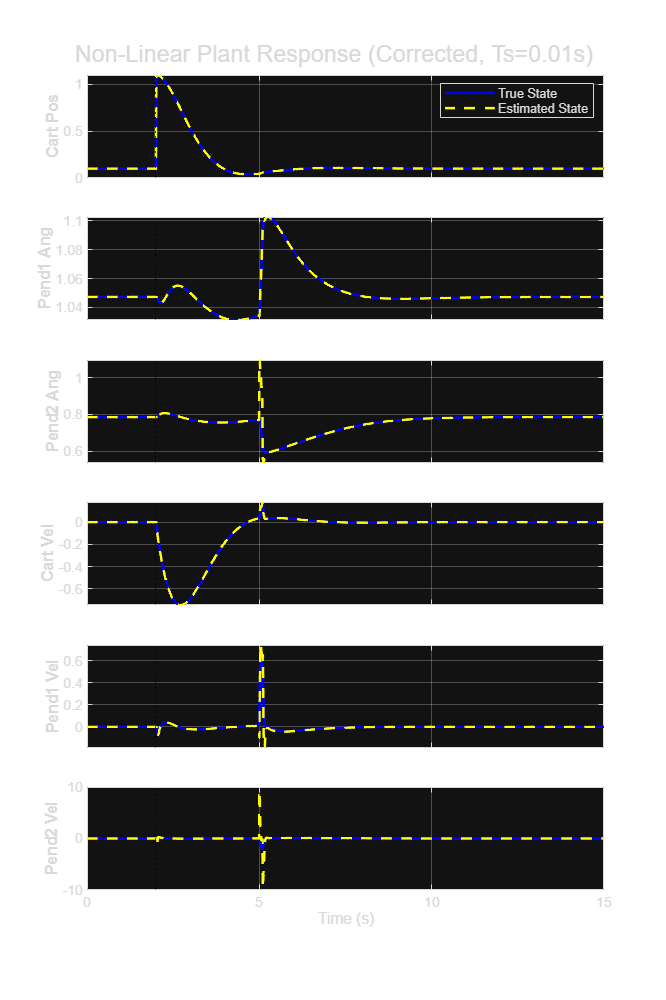

figure('Color', 'w', 'Position', [100, 50, 600, 900]); 
sgtitle(sprintf('Non-Linear Plant Response (Corrected, Ts=%.2fs)', Ts));

state_names = {'Cart Pos', 'Pend1 Ang', 'Pend2 Ang', ...
               'Cart Vel', 'Pend1 Vel', 'Pend2 Vel'};

for i = 1:6
    subplot(6, 1, i);
    plot(Time_hist, X_hist(i,:), 'b', 'LineWidth', 1.5); hold on;
    plot(Time_hist, X_hat_hist(i,:), 'y--', 'LineWidth', 1.5);

    xline(2, 'k:', 'HandleVisibility', 'off'); % attack time reference

    ylabel(state_names{i}, 'FontWeight', 'bold');
    grid on;

    if i == 1, legend('True State', 'Estimated State', 'Location', 'best'); end
    if i < 6, set(gca, 'XTickLabel', []); else, xlabel('Time (s)'); end
end



function dx = plant_dynamics_with_attack(t, x, u, f_handle, B2_d, attack_val)
    dx_nominal = f_handle(x, u); 
    dx = dx_nominal + B2_d * attack_val;
end

%% 1. Setup & Function Handle Creation
if ~exist('f_sym_new_2', 'var')
    error('f_sym_new_2 not found. Please run your symbolic derivation code first.');
end

syms x1 x2 x3 x4 x5 x6 real
syms u_1 u_2 u_3 real
vars_state = [x1; x2; x3; x4; x5; x6];
vars_input = [u_1; u_2; u_3];

f_nonlin_fun = matlabFunction(f_sym_new_2, 'Vars', {vars_state, vars_input});
fprintf('Nonlinear Function Handle Created.\n');

Nonlinear Function Handle Created.



%% 2. Simulation Parameters
Ts = 0.01;      
time_samples = 0:Ts:T_sim;
steps_discrete = length(time_samples);

x_eq = vals(1:6);
u_eq = vals(7:9);
y_eq = C_new * x_eq;

x_current = x_eq; %- [0.5; 0.5; 0.5; 0.5; 0.5; 0.5];        
z_current = zeros(6,1);  % Observer tracks DEVIATION (starts at 0)
u_applied = u_eq;        % Initial absolute input
delta_u_prev = zeros(3,1); 

X_hist = [];
X_hat_hist = [];
Time_hist = [];
%% 3. Hybrid Simulation Loop (Actuator + Sensor Attacks)
fprintf('Starting Hybrid Simulation...\n');

Starting Hybrid Simulation...



% Storage for verification
X_hist = []; X_hat_hist = []; Time_hist = []; 
Y_meas_hist = []; % To store the corrupted measurement

for k = 1:steps_discrete - 1
    t_samp = time_samples(k);
    
    % --- A. Define Actuator Attack (Physical Kick) ---
    % t = 2.0s: Physical impact
    if abs(t_samp - 2.0) < Ts/2
        f_act = 100; % Newtons
    else
        f_act = 0; 
    end
    
    % --- B. Define Sensor Attack (Data Corruption) ---
    % t = 5.0s to 5.5s: Inject constant bias (e.g., 15 degrees)
    if t_samp >= 5.0 && t_samp < 5.1
        f_sens = 0.26; % ~15 degrees in radians
    else
        f_sens = 0;
    end
    
    % --- C. Measurement Step ---
    % The sensor sees the true state + the attack "lie"
    % y_meas = C*x + D2*f_sens
    y_meas = C_new * x_current + D2 * f_sens;
    
    % Deviation for Observer
    delta_y = y_meas - y_eq;
    
    % --- D. Observer Step ---
    % The UIO processes the corrupted delta_y
    z_next = Fd * z_current + Td * Bd * delta_u_prev + Kd_obs * delta_y;
    z_current = z_next;
    
    % Reconstruct State Estimate
    delta_x_hat = z_current + Hd * delta_y;
    x_hat_abs = delta_x_hat + x_eq;
    
    % --- E. Controller Step ---
    % Controller uses x_hat. Ideally, x_hat ignores f_sens.
    delta_u_new = -K_lmi * delta_x_hat; 
    u_applied = delta_u_new + u_eq;    
    delta_u_prev = delta_u_new;
    
    % --- F. Physics Step ---
    % PASS ONLY f_act (Force). DO NOT PASS f_sens (Data).
    tspan = [t_samp, t_samp + Ts];
    ode_physics = @(t,x) plant_dynamics(t, x, u_applied, f_nonlin_fun, B2, f_act);
    
    [t_out, x_out] = ode45(ode_physics, tspan, x_current);
    x_current = x_out(end, :)';
    
    % --- Storage ---
    X_hist = [X_hist, x_out']; 
    X_hat_hist = [X_hat_hist, repmat(x_hat_abs, 1, length(t_out))];
    Time_hist = [Time_hist, t_out'];
    Y_meas_hist = [Y_meas_hist, repmat(y_meas, 1, length(t_out))];
end
fprintf('Simulation Complete.\n');

Simulation Complete.



%% 4. Generate 3D Animation (Robust Rendering)
video_filename = 'DIPC_Final_Attack_6.mp4';
v = VideoWriter(video_filename, 'MPEG-4');
v.FrameRate = 30; 
v.Quality = 100;
open(v);

% --- Parameters ---
CART_W = 0.5; CART_H = 0.2; CART_D = 0.3;
l1 = 0.5; l2 = 0.75;
z_offset1 = 0.03; z_offset2 = -0.03; 

% --- Figure Setup ---
% 'Visible', 'on' is crucial for getframe
fig = figure('Name', 'DIPC 3D Animation', 'Color', 'w', ...
             'Units', 'normalized', 'Position', [0.1 0.1 0.6 0.6], ...
             'Visible', 'on', 'Renderer', 'opengl'); % OpenGL usually smoother for 3D

ax = axes('Parent', fig);
axis(ax, [-3 3 -1 1 -1 1.5]);
view(0, 30); % Front view to see the pendulum swing clearly
grid on; hold on;
xlabel('X (m)'); zlabel('Z (m)');
title('Double Inverted Pendulum - Impulse Attack at t=2.0s');
axis equal;
set(gca, 'ZLim', [-1 2]); % Fix vertical height

% --- Graphics Objects ---
% Ground
patch([-10 10 10 -10], [-2 -2 2 2], [-0.2 -0.2 -0.2 -0.2], [0.9 0.9 0.9], 'EdgeColor', 'none');

% Cart
v_box = [ -0.5 -0.5 -0.5; 0.5 -0.5 -0.5; 0.5 0.5 -0.5; -0.5 0.5 -0.5; ...
          -0.5 -0.5  0.5; 0.5 -0.5  0.5; 0.5 0.5  0.5; -0.5 0.5  0.5];
f_box = [1 2 3 4; 5 6 7 8; 1 2 6 5; 2 3 7 6; 3 4 8 7; 4 1 5 8];
v_box = v_box .* [CART_W, CART_D, CART_H]; 
cart_patch = patch('Faces', f_box, 'Vertices', v_box, 'FaceColor', [0.8 0.2 0.2], 'EdgeColor', 'k');

% Links
hPend1 = plot3([0 0], [0 0], [0 0], '-', 'LineWidth', 5, 'Color', [0.2 0.8 0.2]); 
hPend2 = plot3([0 0], [0 0], [0 0], '-', 'LineWidth', 5, 'Color', [0.2 0.2 0.8]); 
hJoint1 = plot3(0,0,0, 'o', 'MarkerSize', 10, 'MarkerFaceColor', 'k', 'MarkerEdgeColor', 'k');

% --- Animation Loop ---
total_frames = length(Time_hist);
skip = max(1, floor(length(Time_hist) / (T_sim * 30))); 

fprintf('Rendering Video... (Do not minimize the figure window!)\n');

Rendering Video... (Do not minimize the figure window!)



try
    for k = 1:skip:total_frames
        if ~isvalid(fig), break; end 
        
        xc = X_hist(1, k);      
        theta1 = X_hist(2, k);  
        theta2 = X_hist(3, k);  
        
        % Update Cart Vertices
        V_new = v_box + [xc, 0, CART_H/2]; 
        set(cart_patch, 'Vertices', V_new);
        
        % Kinematics
        p0 = [xc, 0, CART_H]; 
        p1 = p0 + [l1*sin(theta1), z_offset1, l1*cos(theta1)];
        p2 = p1 + [l2*sin(theta2), z_offset2, l2*cos(theta2)];
        
        % Update Links
        set(hPend1, 'XData', [p0(1) p1(1)], 'YData', [p0(2) p1(2)], 'ZData', [p0(3) p1(3)]);
        set(hPend2, 'XData', [p1(1) p2(1)], 'YData', [p1(2) p2(2)], 'ZData', [p1(3) p2(3)]);
        set(hJoint1, 'XData', p1(1), 'YData', p1(2), 'ZData', p1(3));
        
        % Follow Cam (Optional: Keeps cart in center)
        % set(gca, 'CameraTarget', [xc, 0, 0.5]);
        % set(gca, 'CameraPosition', [xc, 5, 0.5]);
        
        drawnow; 
        
        % Capture
        frame = getframe(fig); 
        writeVideo(v, frame);
    end
catch ME
    warning('Animation loop stopped: %s', ME.message);
end

close(v);
fprintf('Animation Saved: %s\n', video_filename);

Animation Saved: DIPC_Final_Attack_6.mp4


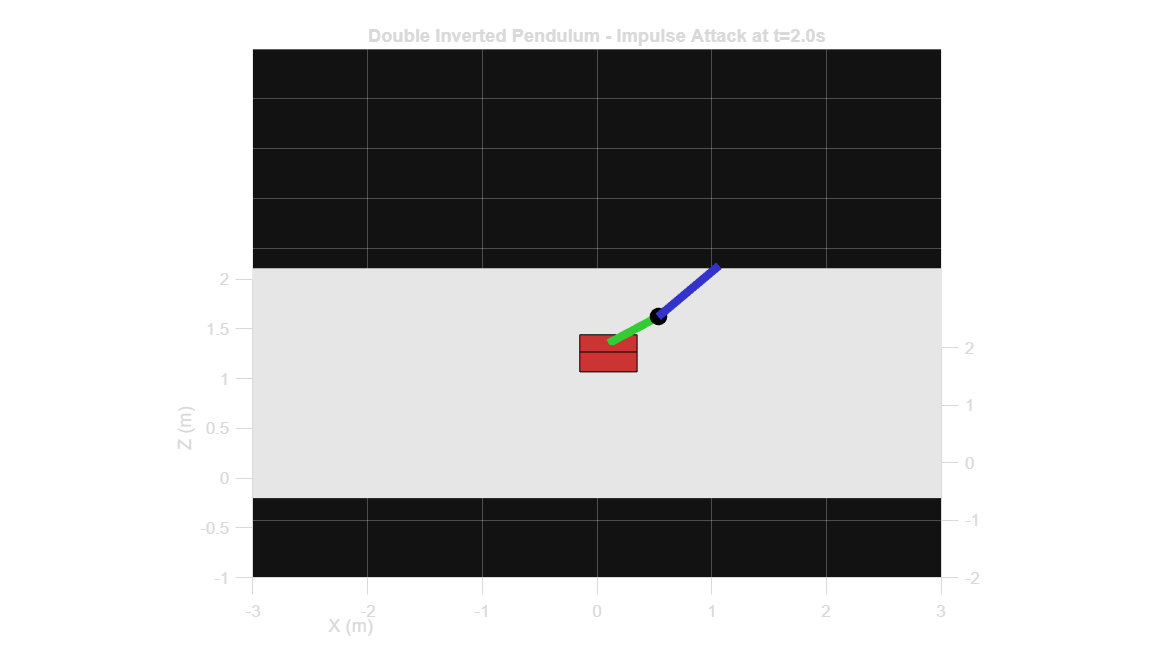


try
    for k = 1:skip:total_frames
        if ~isvalid(fig), break; end % Stop if figure is closed
        
        xc = X_hist(1, k);      
        theta1 = X_hist(2, k);  
        theta2 = X_hist(3, k);  
        
        % Update Cart
        V_new = v_box + [xc, 0, CART_H/2]; 
        set(cart_patch, 'Vertices', V_new);
        
        % Update Joints
        p0 = [xc, 0, CART_H]; 
        p1 = p0 + [l1*sin(theta1), z_offset1, l1*cos(theta1)];
        p2 = p1 + [l2*sin(theta2), z_offset2, l2*cos(theta2)];
        
        % Update Lines & Markers
        set(hPend1, 'XData', [p0(1) p1(1)], 'YData', [p0(2) p1(2)], 'ZData', [p0(3) p1(3)]);
        set(hPend2, 'XData', [p1(1) p2(1)], 'YData', [p1(2) p2(2)], 'ZData', [p1(3) p2(3)]);
        set(hM1, 'XData', p1(1), 'YData', p1(2), 'ZData', p1(3));
        set(hM2, 'XData', p2(1), 'YData', p2(2), 'ZData', p2(3));
        
        set(gca, 'CameraTarget', [xc, 0, 0.5]);
        
        drawnow; % Force update
        
        % Capture Frame
        frame = getframe(fig); % Capture specific figure
        writeVideo(v, frame);
    end
catch ME
    warning('Animation loop failed: %s', ME.message);
    close(v);
end


close(v);
fprintf('Animation Saved: %s\n', video_filename);

Animation Saved: DIPC_Final_Attack_6.mp4



close(v);
fprintf('Animation Saved: %s\n', video_filename);

Animation Saved: DIPC_Final_Attack_6.mp4



function dxdt = plant_dynamics(t, x, u, f_func, B2_d, attack_val)
    dxdt_nominal = f_func(x, u);
    % 2. Add Physical Attack Force
    % The attack_val comes from the main loop (Zero Order Hold)
    dxdt = dxdt_nominal + B2_d * attack_val;
end
